# **demo01 of Im2mesh package**

demo01 - Demonstrate function im2mesh, which use [MESH2D](https://github.com/dengwirda/mesh2d) as mesh generator.

Cite as: Ma, J., & Li, Y. (2025). Im2mesh: A MATLAB/Octave package for generating finite element mesh based on 2D multi-phase image (2.1.5). Zenodo. [https://doi.org/10.5281/zenodo.14847059](https://doi.org/10.5281/zenodo.14847059)

Jiexian Ma, mjx0799@gmail.com. [Project website](https://github.com/mjx888/im2mesh).

## Note

I suggest familiarizing yourself with Im2mesh_GUI before learning Im2mesh package. With graphical user interface, Im2mesh_GUI will help you better understand the workflow and parameters of Im2mesh package.

Im2mesh_GUI: [https://www.mathworks.com/matlabcentral/fileexchange/179684-im2mesh_gui-2d-image-to-finite-element-mesh](https://www.mathworks.com/matlabcentral/fileexchange/179684-im2mesh_gui-2d-image-to-finite-element-mesh)

If you are using Im2mesh package in MATLAB,  you need to install MATLAB Image Processing Toolbox and Mapping Toolbox because Im2mesh package use a few functions in these toolboxes.

## Setup

Before we start, please set folder "Im2mesh_Matlab" as your current folder of MATLAB.

clearvars

Set default image size.

x = 250; y = 250; width = 250; height = 250;
set(groot, 'DefaultFigurePosition', [x,y,width,height])
% To reset:
% set(groot, 'DefaultFigurePosition', 'factory')

Function im2mesh use a mesh generator called [MESH2D](https://github.com/dengwirda/mesh2d) (developed by Darren Engwirda). We can use the following command to add the folder 'mesh2d-master' to the path of MATLAB. 

addpath(genpath('mesh2d-master'))

## Kumamon

Let's start demo01. We'll demostate the usage of function im2mesh.

Import image kumamon.tif.

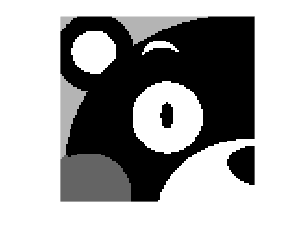

im = imread('kumamon.tif');
if size(im,3) == 3;  im = rgb2gray( im ); end
imshow( im,'InitialMagnification','fit' );

Show the grayscale levels in the image

intensity = unique( im ); 
intensity

intensity = 4×1 uint8 column vector
     0
   100
   180
   255


Let's use function im2mesh to generate meshes based on the kumamon image. We will use default settings. Note that function im2mesh has incorporated the workflow that you saw in im2mesh_GUI: extract polygonal boundaries from image, search & label control points, smooth boundary, simplify boundary, select phase, and generate mesh.

[ vert, tria, tnum ] = im2mesh( im );

 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          6                153                235
         10                171                485
         14                173                534


 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          7                266                235
         10                275               1233
         19                285               1904


 Smooth triangulation...

 -------------------------------------------------------
      |ITER.|          |MOVE(X)|          |DTRI(X)|     
 -------------------------------------------------------
          4                492               1886
          8                143               1886
     

Function im2mesh has 3 ouptut variables: vert, tria, tnum. They defines **linear elements** of generated triangular mesh.

vert - Node data. N-by-2 array.

tria - Node numbering for each triangle. M-by-3 array.

tnum - Label of material phase. P-by-1 array.

We can plot the mesh using function plotMeshes.

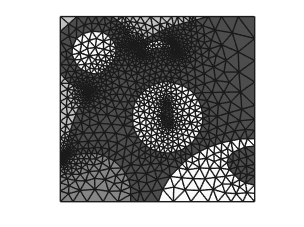

plotMeshes( vert, tria, tnum )

## Mesh quality

We can use function tricost to check the mesh quality. Function tricost is written by by Darren Engwirda.

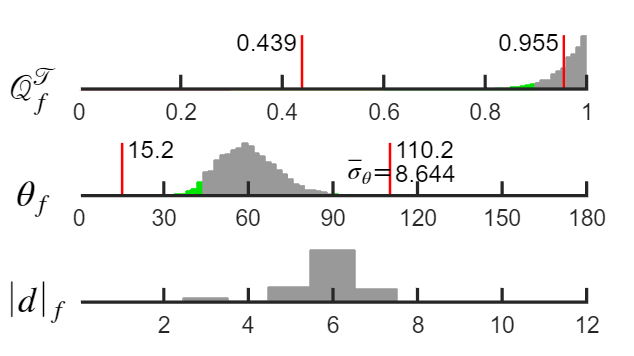

tricost( vert, tria, tnum );

We can get the mean value of Q.

mean(triscr2( vert, tria ))

ans = 0.9549

Wonderful! Let's check the total number of triangles in the mesh.

size( tria, 1 )

ans = 1886

That's a lot of triangles. 

## Change parameter

We can change the parameters of function im2mesh to see whether it help to reduce the number of triangles. 

opt = [];               % initialize. opt is a structure array.
opt.tolerance = 1;      % default value for opt.tolerance is 0.3

[ vert, tria, tnum ] = im2mesh( im, opt );

 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          6                104                133
         10                117                231
         12                118                236


 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          6                175                133
         10                190                709
         17                201                846


 Smooth triangulation...

 -------------------------------------------------------
      |ITER.|          |MOVE(X)|          |DTRI(X)|     
 -------------------------------------------------------
          4                188                838
          8                  7                838



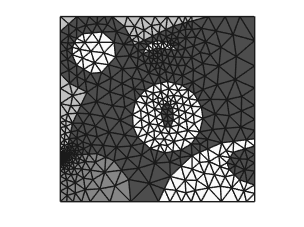

plotMeshes( vert, tria, tnum )

size( tria, 1 )

ans = 838

Now, the number of triangles decreases a lot. That's great.

## Parameters of function im2mesh

As I showed before, there're two ways to call function im2mesh.

Variable opt means options. It's a structure array used to stored input parameters for function im2mesh. We can take a look at the default value of opt.

You don't need to memorize the names of these parameters. The meaning of these parameters are listed the file "Im2mesh functions and parameters.pdf". Please refer to "Im2mesh_GUI Tutorial.pdf" about how to choose the value of these parameters. You may change the default values by editting function setOption in "im2mesh.m".

## Quadratic element

Function im2mesh can also generate quadratic element via the following syntax.

Ouput variables - vert, tria, tnum define **linear elements.**

Ouput variables - vert2, tria2, tnum define **quadratic elements.**

Their meanings are as follows.

vert - Node data. N-by-2 array.

tria - Node numbering for each triangle. M-by-3 array.

tnum - Label of material phase. P-by-1 array.

vert2 - Node data (2nd order element). P-by-2 array. Due to new vertices, the length of vert2 is much longer than vert.

tria2 - Node numbering for each triangle (2nd order element). M-by-6 array.

You can also plot mesh using function plotMeshes, or eveluate mesh quality using function tricost.

## Example 1

Let's show some examples with different opt.

% example 1
opt = [];               % reset opt
opt.tolerance = 0;      % no polyline simplification
[ vert, tria, tnum ] = im2mesh( im, opt );

 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          5                765               1436
         10                801               1960
         19                822               3907


 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          8                908               1436
         10                910               3367
         20                920              11029
         23                922              11089


 Smooth triangulation...

 -------------------------------------------------------
      |ITER.|          |MOVE(X)|          |DTRI(X)|     
 -------------------------------------------------------
          4               3532              10981
     

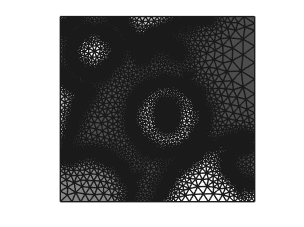

plotMeshes( vert, tria, tnum );

## Example 2

% example 2
opt = [];                       % reset opt
opt.tolerance = 1;
opt.select_phase = [1 2 4];     % select phase for meshing
[ vert, tria, tnum ] = im2mesh( im, opt );

 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          3                 88                121
          9                 99                196


 Refine triangulation...

 -------------------------------------------------------
      |ITER.|          |CDT1(X)|          |CDT2(X)|     
 -------------------------------------------------------
          5                154                121
         10                168                682
         16                173                756


 Smooth triangulation...

 -------------------------------------------------------
      |ITER.|          |MOVE(X)|          |DTRI(X)|     
 -------------------------------------------------------
          4                174                746
          8                  8                746



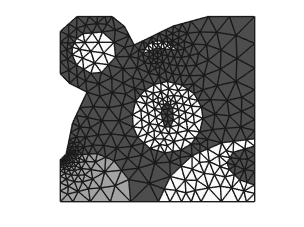

plotMeshes( vert, tria, tnum );

% reset image size
set(groot, 'DefaultFigurePosition', 'factory')

% end of demo